# **Script for  "Personalised metabolic whole-body models for newborns and infants predict growth and biomarkers of inherited metabolic diseases"**

**Authors: Elaine Zaunseder, Ulrike Mütze, Jürgen G. Okun, Georg F. Hoffmann, Stefan Kölker, Vincent Heuveline, and Ines Thiele [1]**

**Abstract: **Extensive whole-body models (WBMs) accounting for organ-specific dynamics have been developed to simulate adult metabolism. However, there is currently a lack of models representing infant metabolism taking into consideration its special requirements in energy balance, nutrition, and growth. In this study, we present the first organ-resolved, sex-specific, anatomically accurate models of newborn and infant metabolism, referred to as infant-whole-body models (infant-WBMs). The infant-WBMs were parameterised to accurately represent the distinct metabolic characteristics of newborns and infants. In particular, we adjusted the changes in organ weights, the energy requirements of brain development, heart function, and thermoregulation, as well as dietary requirements and energy requirements for physical activity. Subsequently, we validated the accuracy of the infant-WBMs by showing that the predicted neonatal and infant growth was consistent with the recommended growth by the World Health Organisation (WHO). We assessed the infant-WBM’s reliability and capabilities for personalisation by simulating 10,000 newborn models, personalised with blood concentration measurements from newborn screening and birth weight. Moreover, we demonstrate that the models can be used to predict changes over time in known blood biomarkers in inherited metabolic diseases. By this, the presented infant-WBMs provide valuable insights into infant metabolism on an organ-resolved level and provide a holistic view of the metabolic processes occurring in infants, considering the unique energy and dietary requirements as well as growth patterns specific to this population. As such, they hold promise for personalised medicine, as they could be a first step to a digital metabolic twin for newborn and infant metabolism for personalised systematic simulations and treatment planning.

**This script presents all functions and simulations used in the infant-WBM manuscript. **

- **3.1** Overview of the reconstruction process resulting in sex-specific, organ-resolved whole-body models of newborn and infant metabolism

- **3.2** Validation - Prediction of growth rate over time

- **3.3 **Validation - Prediction of metabolic fluxes within the infant body

- **3.4** Application 1 - Integrative analysis of metabolome data from 10,000 healthy individuals is enabled by infant-WBMs

- **3.5** Application 2 - Infant-WBMs can be used for biomarker prediction of inherited metabolic diseases

- **3.6** Application 3 - IMD Dietary treatment strategy analysis

- **6.2** Methods - Energy demand reactions

- **6.3** Methods - Nutrition algorithm

%Change Solver to cplex
% This code was tested using the IBM CPLEX SOlver version 12.9
changeCobraSolver('ibm_cplex','QP');

Gurobi installed at this location? 
Licence file current? 
CPXPARAM_Output_WriteLevel                       3
CPXPARAM_Output_CloneLog                         -1
Found incumbent of value 0.000000 after 0.00 sec. (0.00 ticks)

Root node processing (before b&c):
  Real time             =    0.00 sec. (0.00 ticks)
Parallel b&c, 16 threads:
  Real time             =    0.00 sec. (0.00 ticks)
  Sync time (average)   =    0.00 sec.
  Wait time (average)   =    0.00 sec.
                          ------------
Total (root+branch&cut) =    0.00 sec. (0.00 ticks)
Could not find installation of tomlab_cplex, so it cannot be tested
GLPK Simplex Optimizer, v4.42
1 row, 2 columns, 1 non-zero
Preprocessing...
~     0: obj =   0.000000000e+00  infeas =  0.000e+00
OPTIMAL SOLUTION FOUND BY LP PREPROCESSOR

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------

changeCobraSolver('ibm_cplex','LP');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.


## **3.1** Overview of the reconstruction process resulting in sex-specific, organ-resolved whole-body models of newborn and infant metabolism

To create a sex-specific newborn or infant whole-body model at a specific age the function *infantWBM.m *can be applied. This function uses the *create_newborn.m *function, which takes a sex-specific model, where the biomass reactions are updated to enable growth, the infant's weight, age and measured metabolite concentrations from newborn screening (in this case dummy values) as input to create a infant-WBM model. Based on these information the function adapts the model depending on organ weights, diet intake, energy consumption from brain, heart, muscles and heat regulation as well as water balance.

**Input**

- gender='male' for male infants and gender='female' for female infants.

- age in days for simulation age, choose an age between 1-180 days. 

% User input 
gender='male';
age=10;

% Create infant model 
model=infantWBM(gender,age);

### All individual parameters which were used to personalize the model, are saved in model.IndividualParameters

model.IndividualParameters

ans = struct with fields:
               OrgansWeights: {56×3 cell}
                          ID: 'Infant'
                  bodyWeight: 3.5779
                         age: 10
                         sex: 'male'
                   HeartRate: 140
                StrokeVolume: 10
               CardiacOutput: 1400
                  Hematocrit: 0.4000
         MConUrCreatinineMax: 61
         MConUrCreatinineMin: 27
               MConDefaultBc: 20
              MConDefaultCSF: 20
            MConDefaultUrMax: 20
            MConDefaultUrMin: 0
                 CSFFlowRate: 0.0362
            CSFBloodFlowRate: 0.5200
                  UrFlowRate: 171.7392
    GlomerularFiltrationRate: 40
               bloodFlowData: {50×21 cell}
                bloodFlowRow: 5
            bloodFlowPercCol: [2 3]
           bloodFlowOrganCol: 1


### The amount of milk (gr) used as nutrition for the model is saved in model.diet

model.diet

ans = 1×2 cell array
    {'milkmodel(gr)'}    {[534]}


## 3.2 Validation - Prediction of growth rate over time

A critical step in modelling biological systems is the validation process and comparison with the actual organism, in our case, the human infant. An important difference between the metabolic models of adults and infants lies in the capacity of infants to undergo growth, leading to increases in total body weight and individual organ weights.

To simulate growth we use flux balance analysis and maximize the whole-body biomass reaction using the *optimizeWBModel.m* function. The Whole-body biomass reaction is set as objective function with lb and ub between 1-2. The optimization can take **0.5-10 min** to solve. For example, a computed flux value of 1.01 through the whole-body biomass reaction corresponds to a 1% gain in biomass, thus, increasing the body weight gain of the infant by 1%.

**Here, we show an example of growth prediction for one day on the age specified in 3.1: **

%simulate LP
lpSolution = optimizeWBModel(model)

lpSolution = struct with fields:
    origStatText: 'Optimal solution found'
               f: 1.0090
              f0: NaN
              f1: 1.0090
              f2: NaN
               v: [83149×1 double]
               y: [57980×1 double]
               w: [83149×1 double]
               s: [163315×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
            time: 17.8681
           basis: [1×1 struct]
          vars_v: []
          ctrs_y: [105335×1 double]
          ctrs_s: [105335×1 double]
               x: [83149×1 double]


### Growth-prediction over several time steps

For the growth prediction in section 3.2, we iteratively applied FBA (*optimizeWBMmodel.m*) from the COBRA toolbox v3.0.60 using the function* NB_runSimulation.m*. Starting from day one, we maximised the flux through the whole-body biomass reaction (VMH ID: Whole_body_objective_rxn) and used the computed flux solution to update the weight of the infant.  Then, we used the new weight to create a model for the next day by updating all related constraints, and performed another FBA on this updated model, continuing like this until the age of six months. The resulting growth curves are compared to the WHO reference values and to the prediction from the STIG-met model from Nilsson et al [2]. 

**Input**

**simSettings.start**   choose a starting age in days,

**simSettings.end**     choose a ending age in days,

**gender **                    choose the sex of the infant 'male' or 'female'. 

% Settings (USER INPUT)
simSettings.start=10;  % USER INPUT: age(days) the growth evaluation should start 
simSettings.end=11; % USER INPUT:    % end of evaluation  in days %USER INPUT
gender='female';  %USER INPUT: either 'male' oder 'female'

%Create initial model
if strcmp(gender, 'male')
    load('models/babyBoy.mat')
else
    load('models/babyGirl.mat')
end

#### Assign a results PATH to save the simulation results and run simulation results 

simulation_results=NB_runSimulation(model, simSettings);

Starting infant model at age_10 with weight_3.4257

lpSolution = struct with fields:
    origStatText: 'Optimal solution found'
               f: 1.0076
              f0: NaN
              f1: 1.0076
              f2: NaN
               v: [85662×1 double]
               y: [60436×1 double]
               w: [85662×1 double]
               s: [169584×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
            time: 33.3083
           basis: [1×1 struct]
          vars_v: []
          ctrs_y: [109148×1 double]
          ctrs_s: [109148×1 double]
               x: [85662×1 double]


Starting infant model at age_11 with weight_3.4517

lpSolution = struct with fields:
    origStatText: 'Optimal solution found'
               f: 1.0076
              f0: NaN
              f1: 1.0076
              f2: NaN
               v: [85662×1 double]
               y: [60436×1 double]
               w: [85662×1 double]
               s: [169584×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
            time: 19.6277
           basis: [1×1 struct]
          vars_v: []
          ctrs_y: [109148×1 double]
          ctrs_s: [109148×1 double]
               x: [85662×1 double]


% Save simulation results 
results=simulation_results;

### **Growth curve plot **

The simulation results can be plotted over the specified time frame. Here, we load the simulation results from the 180 day simulation, as this can take ~5-10h to finish. 

#### Male infant-WBM

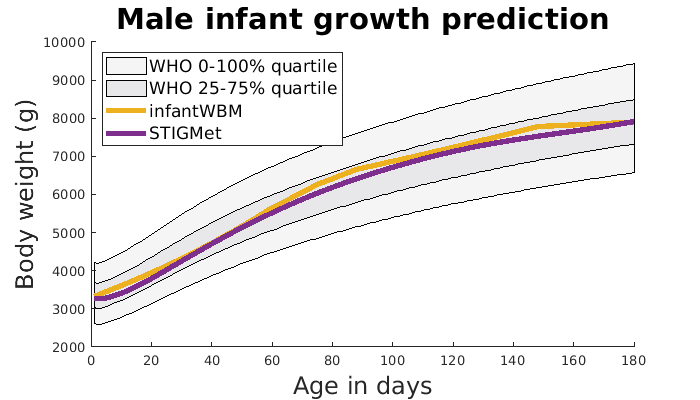

gender='male';
load(strcat('infantWBM_',gender,'_results180.mat'))   
plotInfantGrowth(results,gender)

#### Female infant-WBM

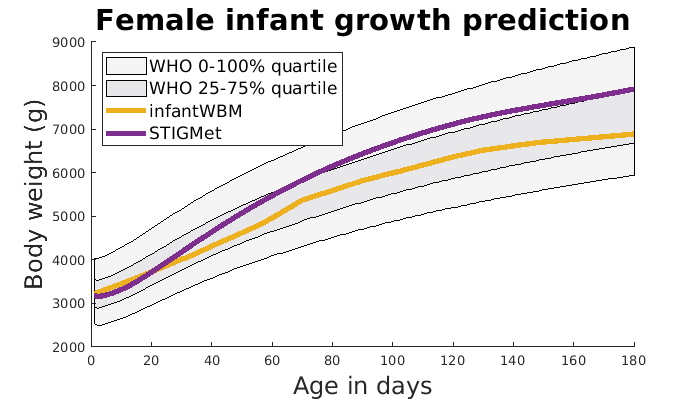

gender='female';
load(strcat('infantWBM_',gender,'_results180.mat'))   
plotInfantGrowth(results,gender)

## 3.3 Validation - Prediction of metabolic fluxes within the infant body

The infant-WBM enables a comprehensive assessment of metabolic fluxes at the organ, subsystem, and reaction level in infants.

The  linear problem (LP) is under-determined, which leads to a polyhedral convex steady-state solution space containing all feasible steady-state solutions. However, to compare the fluxes through different reactions over time, we were interested in a unique flux solution to the problem. Therefore, we applied a second quadratic program (QP), where the Euclidean norm of the flux vector was minimised under the constraint that the optimal solution for the whole-body biomass reaction vwhole body biomass was achieved:

min_v ∥ v ∥

s.t. S · v = 0

lb ≤ v ≤ ub

v_(whole body biomass) = max(cT · v)

gender='female'; % USER INPUT

% To run the evaluation set if statement to 1, however this takes a long
% time. To save time set the statement to 0 and load QP results file. 
if 0
  QP=QPInfants(gender);
else
    load(strcat('results/3_3_Results/',gender,'_QP_fluxes_final.mat'))
end

### **Plotting results**

We determined the aforementioned QP flux vector for each month (days 1, 30, 60, 90, 120, 150, and 180) in the infant’s life using the corresponding infant-WBMs. Then, we evaluated the flux predictions on these days for specific reaction fluxes of interest. 

### 3.3.1 Water balance flux predictions

Evaluation of the QP fluxes over timepoints from 1-180 days of the water intake 'Diet_EX_h2o[d]' with diet and water secretion fluxes though urine 'EX_h2o[u]', sweat 'EX_h2o[sw]', air 'EX_h2o[a]' and faeces 'Excretion_EX_h2o[fe]'.

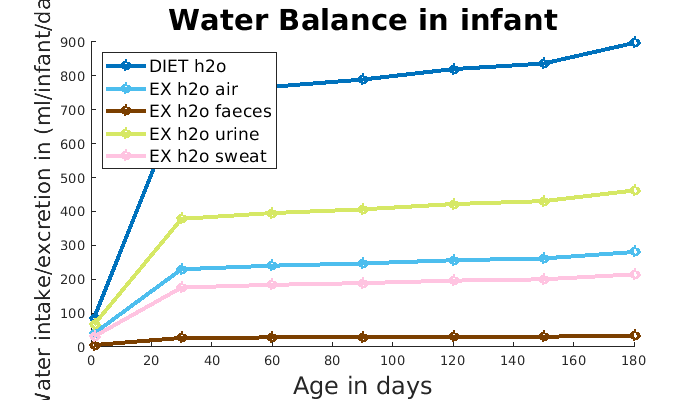

plotQPInfants(QP, 'water')

### 3.3.2 Prediction of ATP synthase in different organs

Evaluation of the QP fluxes over timepoints from 1-180 days of the '_ATPS4m' reaction (ATP synthase) in different organs

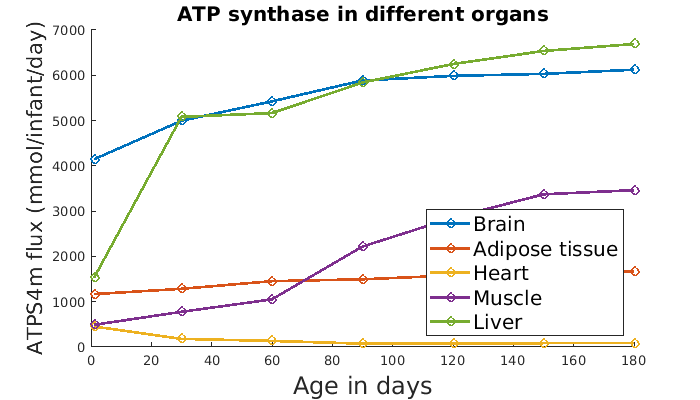

plotQPInfants(QP, 'ATPSynthase')

## 3.4 Application - Integrative analysis of metabolome data from 10,000 healthy individuals is enabled by infant-WBMs

Newborn screening programs worldwide aim at early, ideally, presymptomatic identification of treatable rare diseases, such as IMDs, to reduce morbidity and mortality. For this aim, metabolic, enzymatic, and genetic parameters are analysed with dried blood samples taken in the first days of life (i.e., in Germany at 36-72 h of life). Most metabolic parameters are analysed by tandem mass spectrometry to quantify their concentration. This process generates extensive individualised metabolomic data. 

For the manuscript anonymized data from 10,000 healthy male individuals from Heidelberg University Clinic were evaluated. This data cannot be shared due to privacy restrictions, hence, we show the evaulation on a dummy data set with 100 dummy male newborns. 

% Load baby model 'babyGirl.mat' for female newborns 
load('babyBoy.mat')

%% Load individual data and set age
age=2;
T= readtable('dummy_male100');

%Choose starting and ending entry
start=1;
number_of_models=5;

%give resultsPATH
resultsPATH='results/3_4_Results/'; %USER INPUT

% Option 1: simulate Individuals by predicting their growth rate (SLOW)
%Metabolome=computeIndividualInfants(model, age, T, start, number_of_models, resultsPATH)

% Option 2: (FAST) simulate Individuals by setting growth to growthArray={1.0092; 1.0091; 1.009; 1.0089};
Metabolome=FASTcomputeIndividualInfants(model, age, T, start, number_of_models, resultsPATH);

growth = 1.0092

growth = 1.0092

growth = 1.0092

growth = 1.0092

growth = 1.0092

## 3.5 Application 2: Infant-WBMs can be used for biomarker prediction of inherited metabolic diseases

To further demonstrate the predictive capacity of the infant-WBM models, we first analysed the biomarker prediction for phenylketonuria (PKU) (OMIM: #261600), which is an inborn error of phenylalanine metabolism (synthase of tyrosine from phenylalanine by the Phenylalaninhydroxylase) and is if untreated associated with global development delay and severe intellectual impairment of patients. For the IMD analysis, we used the method established in Thiele et al [3] encoded with the function* performIEMAnalysis.m* in the COBRA Toolbox v3.060. Besides the known biomarkers phenylalanine and tyrosine for PKU, we also evaluated the flux predictions for 27 other metabolite concentrations that are measured in dried blood spots for newborn screening at the UKHD (Figure 4, Table S3) for both male and female infant-WBMs. 

**Input**

**timepoints:** the timepoints of interest e.g. day one ([1])

**sex: **gender of model 'male' or 'female'

**geneMarkerlist: **list of genes for knock out and corresponding biomarkers

**urine:**             0 (no) or 1 (yes) if biomarker should be analysed in urine 

**compartment:**       [bc] if biomarker in blood compartment should be analysed

## Evaluate PKU knock-out for 29 newborn screening metabolites

Since in the following all 29 metabolites are investigated as potential biomarkers for the IMD analysis, this evaluation can take some time.

% give resultsPATH
resultsPATH='results/3_5_Results/';
%set time, model and metabolites
timepoints=[1];
sex = 'female'; %'male' for male infant wbm
person= 'infant';

% gene (5053.1 for PKU) and metabolite list with metabolites of interest 
geneMarkerList = {'5053.1'    'ala_L;arg_L;argsuc;asp_L;crn;c10crn;ttdcrn;pmtcrn;acrn;pcrn;c4crn;ivcrn;c51crn;c6crn;c8crn;citr_L;glu_L;c5dc;gly;hmcr;his_L;met_L;orn_D;phe_L;pro_L;thr_L;trp_L;tyr_L;val_L'};
urine = 0; % test for urine metabolites
compartment = {'[bc]'};

%run IEMAnalysis and save results
 [IEMSolutions,IEMTable]=timepointIEMAnalysis(person,resultsPATH,timepoints, sex, geneMarkerList, urine, compartment)

DM_ala_L[bc]
DM_arg_L[bc]
DM_argsuc[bc]
DM_asp_L[bc]
DM_crn[bc]
DM_c10crn[bc]
DM_ttdcrn[bc]
DM_pmtcrn[bc]
DM_acrn[bc]
DM_pcrn[bc]
DM_c4crn[bc]
DM_ivcrn[bc]
DM_c51crn[bc]
DM_c6crn[bc]
DM_c8crn[bc]
DM_citr_L[bc]
DM_glu_L[bc]
DM_c5dc[bc]
DM_gly[bc]
DM_hmcr[bc]
DM_his_L[bc]
DM_met_L[bc]
DM_orn_D[bc]
DM_phe_L[bc]
DM_pro_L[bc]
DM_thr_L[bc]
DM_trp_L[bc]
DM_tyr_L[bc]
DM_val_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 29×4 cell array
    {'5053'}    {'DM_ala_L[bc]' }    {'534.3127'}    {'519.3895'}
    {'5053'}    {'DM_arg_L[bc]' }    {'157.909' }    {'154.1385'}
    {'5053'}    {'DM_argsuc[bc]'}    {'84.2505' }    {'82.0781' }
    {'5053'}    {'DM_asp_L[bc]' }    {'534.3717'}    {'519.5185'}
    {'5053'}    {'DM_crn[bc]'   }    {'50'      }    {'50'      }
    {'5053'}    {'DM_c10crn[bc]'}    {'20.2653' }    {'20.2653' }
    {'5053'}    {'DM_ttdcrn[bc]'}    {'50'      }    {'50'      }
    {'5053'}    {'DM_pmtcrn[bc]'}    {'50'      }    {'50'      }
    {'5053'}    {'DM_acrn[bc]'  }    {'50'      }    {'50'      }
    {'5053'}    {'DM_pcrn[bc]'  }    {'50'      }    {'50'      }
    {'5053'}    {'DM_c4crn[bc]' }    {'3.1646'  }    {'3.1646'  }
    {'5053'}    {'DM_ivcrn[bc]' }    {'3.7634'  }    {'3.7633'  }
    {'5053'}    {'DM_c51crn[bc]'}    {'17.0451' }    {'17.0451' }
    {'5053'}    {'DM_c6crn[bc]' }    {'10.0245' }    {'10.0245' }
    {'5053'}    {'DM_c8crn[bc]' }    {'13.4963' }

#### Plot results of relative flux change

The above computation can takes some time. Hence, also the end results can be loaded 

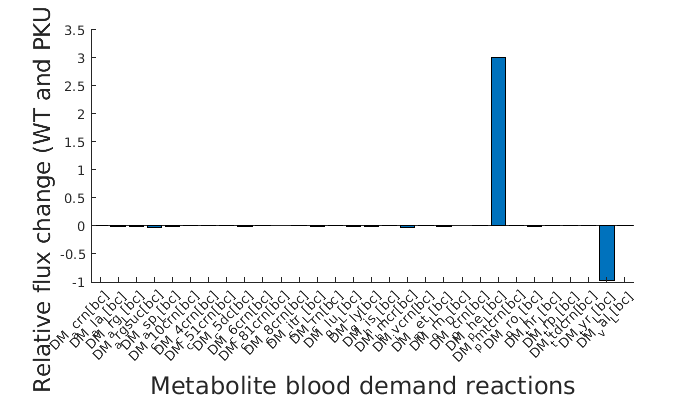

load('NBS_IEMTable_male.mat')

% calculate relative flux change
T=str2double(IEMTable(:,3:4));
T(:,3)=(T(:,2)-T(:,1))./T(:,1);

bar(categorical(IEMTable(:,2)),T(:,3))
set(gca,'box','off')
xlabel('Metabolite blood demand reactions','FontSize',18,'FontName', 'Arial')
ylabel('Relative flux change (WT and PKU model)', 'FontSize',17,'FontName', 'Arial')

#### **IEM Analysis for infants at age 1 90 and 180 days for 5 IEMs**

% give resultsPATH
resultsPATH='results/3_5_Results/';
%set time, model and metabolites
timepoints=[1];
sex = 'female';
person='infant';

geneMarkerList = {
    % % gene biomarker list
 %  '3712.1'    'ivcrn' % IVA
%  '2639.1'    'c5dc' % GA1
  '5053.1'    'phe_L;tyr_L'%;4hphac;phpyr' %PKU
%  '2629.1'    'gluside_hs' %Gaucher diesease GBA1 / GD1
%  '8942.1'    'C02470;kynate' %Kynuric deficiency
  };
compartment = {'[bc]'};

%run IEMAnalysis and save results
[IEMSolutions,IEMTable]=timepointIEMAnalysis(person,resultsPATH,timepoints, sex, geneMarkerList, urine, compartment)

DM_phe_L[bc]
DM_tyr_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 2×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'2.234' }    {'8.2444' }
    {'5053'}    {'DM_tyr_L[bc]'}    {'9.7316'}    {'0.84526'}


#### IEM analysis for adult WBM, Harvey and Harvetta

% give resultsPATH
resultsPATH='results/3_5_Results/';
%set time, model and metabolites
timepoints=[1];
sex = 'female'; %'male' for Harvey
person='adult';

geneMarkerList = {
    % % gene biomarker list
%   '3712.1'    'ivcrn' % IVA
%  '2639.1'    'c5dc' % GA1
  '5053.1'    'phe_L;tyr_L'%;4hphac;phpyr' %PKU
%  '2629.1'    'gluside_hs' %Gaucher diesease GBA1 / GD1
%  '8942.1'    'C02470;kynate' %Kynuric deficiency
  };
compartment = {'[bc]'};

%run IEMAnalysis and save results
[IEMSolutions,IEMTable]=timepointIEMAnalysis(person,resultsPATH,timepoints, sex, geneMarkerList, urine, compartment)

DM_phe_L[bc]
DM_tyr_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 2×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'6.1474' }    {'24.5895'}
    {'5053'}    {'DM_tyr_L[bc]'}    {'43.2006'}    {'18.6111'}


## 3.6 Dietary Treatment

We analyse the response of the infant-WBMs to dietary interventions for PKU. The IMD analysis showed that the infant-WBMs predict an increase or decrease of a biomarker flux caused by the respective in silico gene knockout in an IMD model. For the dietary interventions, we investigate whether this predicted change can be attenuated through applying an in silico dietary treatment strategy. 

% give resultsPATH
resultsPATH='results/3_6_Results/';

%set time, model and metabolites
timepoints=[1];
sex = 'female'; %'male' for male infant wbm

% gene (5053.1 for PKU) and metabolite list with metabolites of interest 
urine = 0; % test for urine metabolites
compartment = {'[bc]'}; 

### (A) First dietary strategy PKU

For PKU patients, a highly restrictive low-phenylalanine diet directly starting after birth is the most important dietary recommendation [7]. In PKU patients, a low-phenylalanine diet is achieved by restricting but not eliminating natural food to allow some phenylalanine intake as it is an essential amino acid [7]. Additionally, an amino acid-based, phe-free formula or amino acid-based medical food is added to provide sufficient nutrition [7]. 

strategy.target='Diet_EX_phe_L[d]';
geneMarkerList = {   '5053.1'    'phe_L' };
strategies=[-0.25 -0.5 -0.6 -0.75]; % dietary INCREASE

for i=1:length(strategies)
    strategy.percent=strategies(i); 
    %run IEMAnalysis and save results
    [IEMSolutions,IEMTable]=IEMDietaryTreatment(strategy,resultsPATH,timepoints, sex, geneMarkerList, urine, compartment)
end

DM_phe_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'1.609'}    {'6.4146'}


DM_phe_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'0.984'}    {'3.9147'}


DM_phe_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'0.734'}    {'2.9148'}


DM_phe_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_phe_L[bc]'}    {'0.35378'}    {'1.4147'}


###   (B) Second dietary strategy PKU

  Furthermore, the supplementation of tyr has been tested to increase the plasma tyr levels found to be low in PKU patients [8].

strategy.target='Diet_EX_tyr_L[d]';
geneMarkerList = {   '5053.1'    'tyr_L' };
strategies=[0.1 0.2 0.25]; % dietary INCREASE

for i=1:length(strategies)
    strategy.percent=strategies(i); 
    %run IEMAnalysis and save results
    [IEMSolutions,IEMTable]=IEMDietaryTreatment(strategy,resultsPATH,timepoints, sex, geneMarkerList, urine, compartment)
end

DM_tyr_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_tyr_L[bc]'}    {'9.8816'}    {'0.99527'}


DM_tyr_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_tyr_L[bc]'}    {'10.0317'}    {'1.1453'}


DM_tyr_L[bc]


IEMSolutions = struct with fields:
    G_5053_1: [1×1 struct]


IEMTable = 1×4 cell array
    {'5053'}    {'DM_tyr_L[bc]'}    {'10.1067'}    {'1.2203'}


## 6.2 Methods Energy demands

Organ-specific energy requirements are quite different between infants and adults (Butte et al [4]) and had to be adapted to represent the requirements for healthy infant development. For the proper development of the brain, we implemented these energy requirements by adjusting the lower bound on the brain ATP reaction (VMH ID: Brain_DM_atp_c_), which monotonously increases in accordance with the age of the infant-WBM. Similarly, the heart energy requirement is infant-specific, depending on the infant's heart weight. With increasing age, activity-based energy requirements also increase, which we accounted for by adding constraints on the muscle ATP demand reaction (VMH ID: Muscle_DM_atp_c_) in accordance with a published activity model [2]. Another important infant-specific energy demand is thermoregulation, which maintains the infant's body temperature, as infants cannot shiver before the age of six months. We implemented the energy requirement for the non-shivering thermogenesis process in the adipose tissue.

This graph presents the lower bounds (lb) on ATP demand reactions in brain, heart, muscle and adipose tissue in mmol/day/person during the first six months of a male infant's life. 

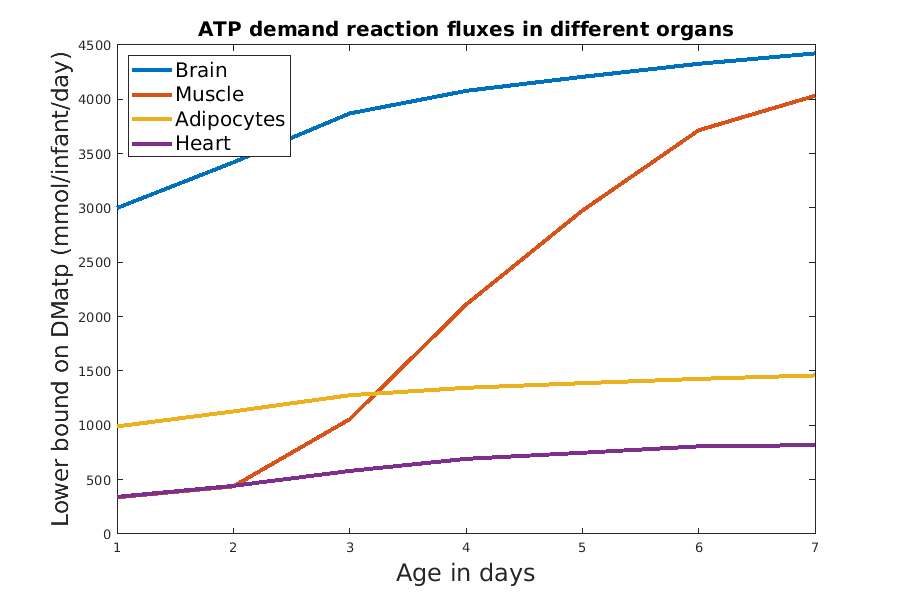

%load model
gender='male'; %'female' for female infant-WBM
timepoints=[1 30 60 90 120 150 180];
for i=1: length(timepoints)
    age=timepoints(i);
    model=infantWBM(gender, age);
    LP.lb(age,:)=model.lb;
end
LP.rxns=model.rxns;

% Make plot
brain=LP.lb(timepoints,(ismember(LP.rxns,'Brain_DM_atp_c_')));
muscle=LP.lb(timepoints,(ismember(LP.rxns,'Muscle_DM_atp_c_')));
adipocytes=LP.lb(timepoints,(ismember(LP.rxns,'Adipocytes_DM_atp_c_')));
heart=LP.lb(timepoints,(ismember(LP.rxns,'Heart_DM_atp_c_')));

fig = figure(); 
fig.Position(3:4) = [900,600];
%plot lower bounds
plot(brain, 'LineWidth', 3.0,'DisplayName', 'Brain')
hold on
plot(muscle, 'LineWidth', 3.0,'DisplayName', 'Muscle')
hold on
plot(adipocytes, 'LineWidth', 3.0,'DisplayName', 'Adipocytes')
hold on
plot(heart, 'LineWidth', 3.0,'DisplayName', 'Heart')
hold off

xlabel('Age in days','FontSize',18,'FontName', 'Arial')
ylabel('Lower bound on DMatp (mmol/infant/day)', 'FontSize',17,'FontName', 'Arial')
title('ATP demand reaction fluxes in different organs', 'FontSize',15,'FontName', 'Arial')
legend('Location','northwest', 'FontSize', 15)

## 6.3 Nutrition algorithm

The nutritional composition of the human milk diet varies over time and between mothers. However, for comparability of our simulation results, and in the absence of personalised dietary data, we assumed the breast milk composition to be unchanged over time (except for the adaptations listed in the Method section).

Sometimes the personalised infant-WBMs, which were personalised based on sex, birth weight, and newborn screening metabolomic data, can be infeasible, as we are working with real data. For those infeasible models, we used a nutrition algorithm developed by Weston et al [5], implemented in the COBRA toolbox v3.0 [6], to identify missing diet components that when added could render the LP problem feasible.

% Create infeasible infant model as example by setting lysine to 0
modelInfeasible=infantWBM('male',10);
modelInfeasible.lb(strcmp(model.rxns,'Diet_EX_lys_L[d]'))=0;
modelInfeasible.ub(strcmp(model.rxns,'Diet_EX_lys_L[d]'))=0;

% Determine diet addition to obtain a specific growth rate with a model
growth_rate=1.009;
modelInfeasible.lb(strcmp(modelInfeasible.rxns,'Whole_body_objective_rxn'))=growth_rate;
modelInfeasible.ub(strcmp(modelInfeasible.rxns,'Whole_body_objective_rxn'))=growth_rate;

[viable_model, point1, points2, diet]=findViableDiet(modelInfeasible, 'Diet_EX_');
diet

diet = 1×2 table
             Food Rxn               Flux 
    ___________________________    ______

    {'Adding_Diet_EX_lys_L[d]'}    -3.719


## References

[1] Elaine Zaunseder, Ulrike Mütze, Jürgen G. Okun, Georg F. Hoffmann, Stefan Kölker, Vincent Heuveline, Ines Thiele, Personalised metabolic whole-body models for newborns and infants predict growth and biomarkers of inherited metabolic diseases, bioRxiv,[https://www.biorxiv.org/content/10.1101/2023.10.20.563364v1](https://www.biorxiv.org/content/10.1101/2023.10.20.563364v1)

[2] [Nilsson, A., Mardinoglu, A., and Nielsen, J. (2017). Predicting growth of the  healthy infant using a genome scale metabolic model. Npj Systems Biology and Applications, 3(1), 3.](http://www.nature.com/articles/s41540-017-0004-5)

[3] Thiele, Ines and Sahoo, Swagatika and Heinken, Almut and Hertel, Johannes and Heirendt, Laurent and Aurich, Maike K and Fleming, Ronan MT, Personalized whole-body models integrate metabolism, physiology, and the gut microbiome, Molecular Systems Biology (2020)16:e8982 [https://doi.org/10.15252/msb.20198982](https://doi.org/10.15252/msb.20198982)

[4] Butte, Nancy F. and Moon, Jon K. and Wong, William W. and Hopkinson, Judy M. and Smith, E.O., Energy requirements from infancy to adulthood, The American Journal of Clinical Nutrition, 1995, [https://doi.org/10.1093/ajcn/62.5.1047S](https://doi.org/10.1093/ajcn/62.5.1047S)

[5] B. Weston, I. Thiele, A nutrition algorithm to optimize feed and medium composition using genome-scale metabolic models, 2023, [https://www.sciencedirect.com/science/article/pii/S1096717623000186](https://www.sciencedirect.com/science/article/pii/S1096717623000186)

[6] Laurent Heirendt et al, Creation and analysis of biochemical constraint-based models using the COBRA Toolbox v. 3.0, 2019, [https://www.nature.com/articles/s41596-018-0098-2](https://www.nature.com/articles/s41596-018-0098-2)

[7] Erin MacLeod and Denise Ney. Nutritional management of phenylketonuria. Annales Nestle [English ed.], 68:58–69, 06 2010. [10.1159/000312813 ](https://doi.org/10.1159/000312813)

[8] LR Kalsner, FJ Rohr, KA Strauss, MS Korson, and HL Levy. Tyrosine supplementation in phenylketonuria: diurnal blood tyrosine levels and presumptive brain influx of tyrosine and other large neutral amino acids. The Journal of pediatrics, 139(3):421–427, 2001.[  10.1067/mpd.2001.117576 ](https://doi.org/10.1067/mpd.2001.117576)